# Exercise 6.3 - Echo cancellation

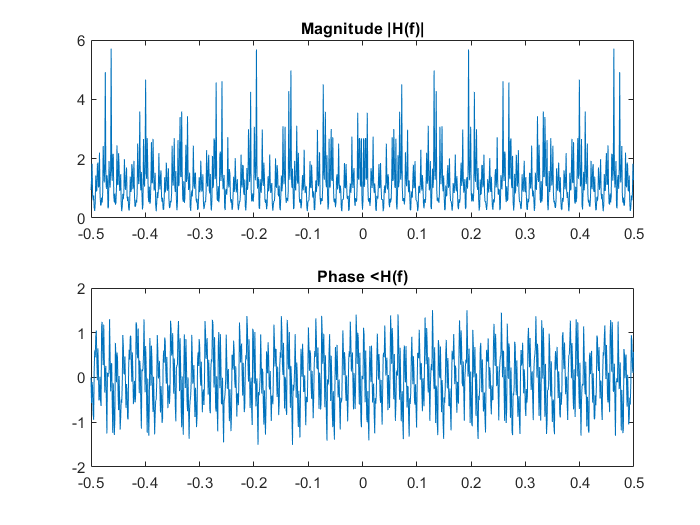

% Import the audio signal generated during lab 3.
[kickEco, fs] = audioread('audio\output3_4.wav');
%sound(kickEco, fs)

% Input and output coefficients of the original signal.
eco1 = 40e-3;
eco2 = 70e-3;
rev1 = 25e-3;

% We copy over the exact same echo and reverb configuration.
numSamplesEco1 = round(fs * eco1) + 1;
numSamplesEco2 = round(fs * eco2) + 1;
numSamplesRev1 = round(fs * rev1) + 1;
b = zeros(1, numSamplesEco2);
b(1) = 1;
b(numSamplesEco1) = 0.5;
b(numSamplesEco2) = 0.25;
a = zeros(1, numSamplesRev1);
a(1) = 1;
a(numSamplesRev1) = 0.65;

%% Inverse filter configuration.
% y[n] = x[n] + ky[n - R]   -> Original system.
% y[n] + ky[n - R] = x[n]   -> Inverse system.
% Hinv(f) = 1 / H(f)
aInv = b;
bInv = a;

% Compute the frequency response of the inverse system (Hinv(f)).
N = 1024;
[Hinv, w] = freqz(bInv, aInv, N, 'whole');

% Shift the spectrum to the origin.
f = w / (2 * pi) - 0.5;
H = fftshift(Hinv);

% Plot the amplitude and phase of Hinv(f).
subplot(211), plot(f, abs(Hinv)), title('Magnitude |H(f)|');
subplot(212), plot(f, angle(Hinv)), title('Phase <H(f)');


% Apply the inverse filter and play the audio signal.
y = filter(bInv, aInv, kickEco);
sound(y, fs)